# Plot Confidence Ellipses

In this script, we construct an artificial covariance matrix and plot its confidence ellipsis.

Author: H. Martin Buecker, [buecker@acm.org](mailto:buecker@acm.org), Copyright 2013-2017, Date: 02/02/2017

%close all;
clear variables;

## Create Matrix

Let


$$
C =
\left[
\begin{array}{cc}
  \sigma_{1}^2  & \sigma_{12} \\
  \sigma_{12}   & \sigma_{2}^2
\end{array}
\right]
$$


be a $2 \times 2$ covariance matrix whose entries area as follows:

- $\sigma_1$ and $\sigma_2$ represent the uncertainties in some parameters $\theta_1$ and $\theta_2$

- $\sigma_{12} = \rho \sigma_1  \sigma_2$ represents the correlation with correlation coefficient $0 \leq \rho \leq 1$.

Now suppose that these entries depend on some experimental condition $x$. The following statements generate such a matrix in some artifical way.

sigma1 = @(x) exp(0.5*x);
sigma2 = @(x) 4*sin(x);
rho = 0.8;
C = @(x) [sigma1(x)*sigma1(x)      rho*sigma1(x)*sigma2(x);...
          rho*sigma1(x)*sigma2(x)  sigma2(x)*sigma2(x)];

% A covarianve matrix is now available via something like
C(0.4)

ans =     1.4918    1.5220
    1.5220    2.4263


## Plot Conficence Ellipsis

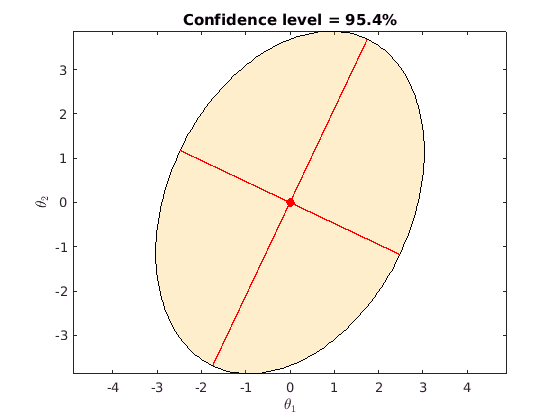

x = 0.4;
mean = [0; 0];
plot_confidence_ellipsis(C(x),mean);

## Vary Experimental Condition

Now, interactively try other values for the design variable `x`

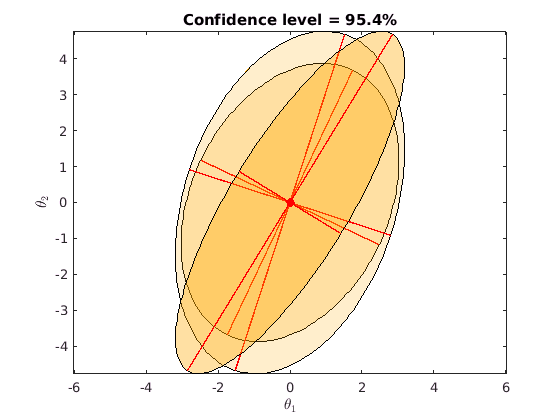

x1 = 0.5;
plot_confidence_ellipsis(C(x1),mean);